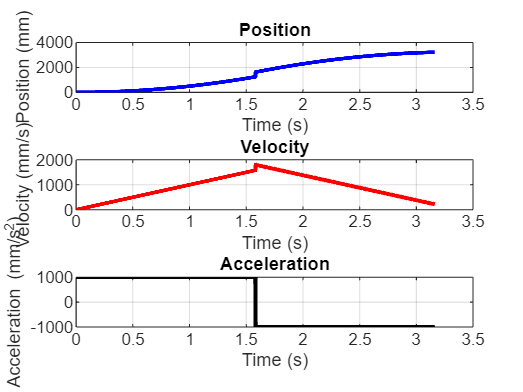

% Các tham số
a_max = 1000;       % gia tốc tối đa (mm/s^2)
v_max = 1800;       % tốc độ tối đa (mm/s)
d = 2500;           % khoảng cách (mm) từ A đến B
dt = 0.001;         % bước thời gian (s)

% Tính thời gian gia tốc
t_acc = v_max / a_max;   % thời gian gia tốc (s)
d_acc = 0.5 * a_max * t_acc^2;  % khoảng cách gia tốc (mm)

if 2*d_acc >= d
    t_acc = sqrt(d / a_max);
    t_const = 0;
    T = 2 * t_acc;
else
    t_const = (d - 2*d_acc) / v_max;
    T = 2 * t_acc + t_const;
end

t = 0:dt:T;
N = length(t);

pos = zeros(size(t));    % vị trí (mm)
vel = zeros(size(t));    % tốc độ (mm/s)
acc = zeros(size(t));    % gia tốc (mm/s^2)

for i = 1:N
    if t(i) <= t_acc
        % Giai đoạn gia tốc
        acc(i) = a_max;
        vel(i) = a_max * t(i);
        pos(i) = 0.5 * a_max * t(i)^2;
    elseif t(i) <= (t_acc + t_const)
        % Giai đoạn tốc độ không đổi
        acc(i) = 0;
        vel(i) = v_max;
        pos(i) = d_acc + v_max * (t(i) - t_acc);
    else
        % Giai đoạn giảm tốc
        t_dec = t(i) - (t_acc + t_const);
        acc(i) = -a_max;
        vel(i) = v_max - a_max * t_dec;
        pos_start_dec = d_acc + v_max * t_const;
        pos(i) = pos_start_dec + v_max * t_dec - 0.5 * a_max * t_dec^2;
    end
end

figure;

subplot(3,1,1);
plot(t, pos, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Position (mm)');
title('Position');
grid on;

subplot(3,1,2);
plot(t, vel, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Velocity (mm/s)');
title('Velocity');
grid on;

subplot(3,1,3);
plot(t, acc, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Acceleration (mm/s^2)');
title('Acceleration');
grid on;

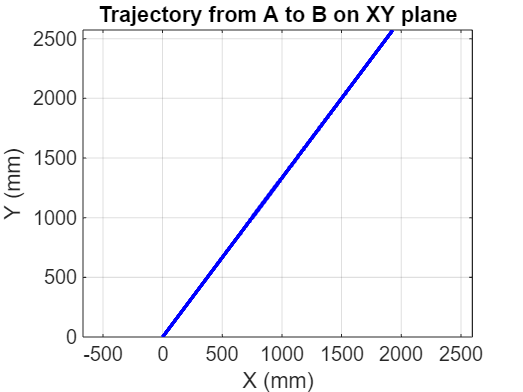


% Tính tọa độ theo trục Oxy từ quãng đường pos
x0 = 0; y0 = 0;
x1 = 1500; y1 = 2000;
dx = x1 - x0;
dy = y1 - y0;
theta = atan2(dy, dx);

x = x0 + pos * cos(theta);
y = y0 + pos * sin(theta);

% Vẽ chuyển động theo mặt phẳng Oxy
figure;
plot(x, y, 'b', 'LineWidth', 2);
xlabel('X (mm)');
ylabel('Y (mm)');
title('Trajectory from A to B on XY plane');
axis equal;
grid on;